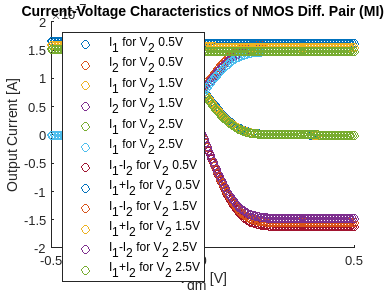

clear
data0 = load('p0.txt');
data1 = load('p1.txt');
data2 = load('p2.txt');
data3 = load('p3.txt');

vdm = data0(:, 1);
V1 = data0(:, 2);
V2 = data1(:, 2);
V3 = data2(:, 2);
V4 = data3(:, 2);
I1 = data0(:, 3);
I2 = data0(:, 4);

II1 = I1-I2;
IP1 = I1+I2;

I3 = data1(:, 3);
I4 = data1(:, 4);

II2 = I3-I4;
IP2 = I3+I4;

I5 = data2(:, 3);
I6 = data2(:, 4);

II3 = I5-I6;
IP3 = I5+I6;

I7 = data3(:, 3);
I8 = data3(:, 4);

II4 = I7-I8;
IP4 = I7+I8;

hold on;
plot(vdm, [I1, I2, I3, I4, I5, I6, II1, IP1, II2, IP2, II3, IP3], 'o');
title("Current-Voltage Characteristics of NMOS Diff. Pair (MI)");
xlabel("V_{dm} [V]");
ylabel("Output Current [A]");
legend("I_1 for V_2 0.5V", "I_2 for V_2 0.5V", ...
    "I_1 for V_2 1.5V", "I_2 for V_2 1.5V", ...
    "I_1 for V_2 2.5V", "I_1 for V_2 2.5V", ...
    "I_1-I_2 for V_2 0.5V", "I_1+I_2 for V_2 0.5V", ...
    "I_1-I_2 for V_2 1.5V", "I_1+I_2 for V_2 1.5V", ...
    "I_1-I_2 for V_2 2.5V", "I_1+I_2 for V_2 2.5V", "location", "southwest");
hold off;

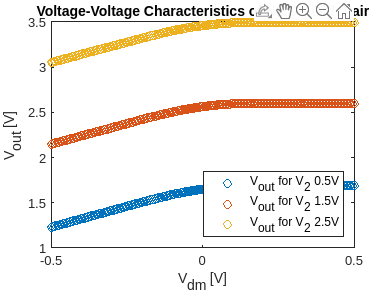

plot(vdm, [V1, V2, V3], 'o');
title("Voltage-Voltage Characteristics of NMOS Diff. Pair");
xlabel("V_{dm} [V]");
ylabel("V_{out} [V]");
legend("V_{out} for V_2 0.5V", ...
    "V_{out} for V_2 1.5V", ...
    "V_{out} for V_2 2.5V", "location", "southeast");

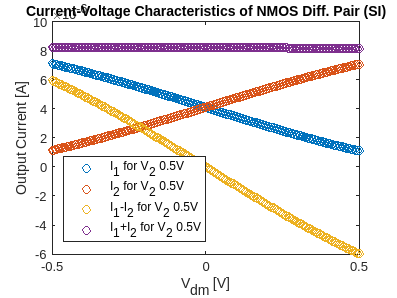


plot(vdm, [I7, I8, II4, IP4], 'o');
title("Current-Voltage Characteristics of NMOS Diff. Pair (SI)");
xlabel("V_{dm} [V]");
ylabel("Output Current [A]");
legend("I_1 for V_2 0.5V", "I_2 for V_2 0.5V", ...
    "I_1-I_2 for V_2 0.5V", "I_1+I_2 for V_2 0.5V", ...
    "location", "southwest");